%% manual_shelltop_annotator.m
% Manual shell-top annotation tool for extracted validation subsets
%
% PURPOSE
%   Frame-by-frame manual annotation of the shell-top point on time-ordered
%   side-view still images, with optional fixed bed-line support and
%   optional visibility-class labels.
%
% DESIGNED FOR
%   - Locked-evaluation and stress-test extracted subsets
%   - Two independent annotators
%   - Blinded first-pass annotation (no automatic tracker outputs shown)
%
% OUTPUTS
%   1) CSV file with one row per frame
%   2) MAT file containing all annotations and settings
%
% MAIN FEATURES
%   - Click shell-top point manually
%   - Auto-advance to next frame after left click
%   - Move forward/backward through frames
%   - Jump to any frame
%   - Mark visibility class:
%         1 = clear
%         2 = moderate ambiguity
%         3 = high ambiguity
%   - Save progress at any time
%   - Optionally load a fixed bed line from file
%   - Optionally compute bed-referenced shell height and manual burrow depth

clear; close all; clc;

%% =====================================================================
%                         USER PARAMETERS
% ======================================================================

params.folder            = 'E:\Computer vision Paper\dataset_2\subset_1';
params.pattern           = 'Image*.tif';
params.annotator_id      = 'A2';
params.output_dir        = params.folder;

params.frame_rate        = 0.5;      % Hz
params.dt                = 1 / params.frame_rate;
params.mm_per_px         = 1/35.19;  % mm/px

% Optional shell length (needed only if you want a burrow-depth estimate)
params.mussel_length_px  = [];
params.mussel_length_mm  = 81.33;
if isempty(params.mussel_length_px) && ~isempty(params.mussel_length_mm) && ~isempty(params.mm_per_px)
    params.mussel_length_px = params.mussel_length_mm / params.mm_per_px;
end

% Optional fixed bed line
params.use_bedline       = true;
params.bedline_mode      = 'load_or_draw';   % 'none' | 'load_or_draw' | 'draw'
params.bedline_file      = fullfile(params.folder, 'bed_line.mat');

% Display settings
params.show_zoom_panel   = true;
params.zoom_half_width   = 120;
params.zoom_half_height  = 120;
params.marker_size       = 10;
params.line_width        = 1.5;
params.font_size         = 12;

% Autosave
params.autosave_every    = 25;

%% =====================================================================
%                           LOAD IMAGES
% ======================================================================

files = dir(fullfile(params.folder, params.pattern));
assert(~isempty(files), 'No files found matching pattern: %s', params.pattern);

[~, idx] = sort_nat({files.name});
files = files(idx);

nFrames = numel(files);
fprintf('Loaded %d frames from %s\n', nFrames, params.folder);

Loaded 3000 frames from E:\Computer vision Paper\dataset_2\subset_1



%% =====================================================================
%                        LOAD OR DEFINE BED LINE
% ======================================================================

bed = struct('enabled', false, 'x1', [], 'y1', [], 'x2', [], 'y2', []);

if params.use_bedline
    firstIm = imread(fullfile(params.folder, files(1).name));

    switch lower(params.bedline_mode)
        case 'none'
            bed.enabled = false;

        case 'load_or_draw'
            if exist(params.bedline_file, 'file')
                S = load(params.bedline_file);
                bed = parse_bedline_struct(S);
                fprintf('Loaded bed line from %s\n', params.bedline_file);
            else
                bed = draw_bedline(firstIm, params);
                save(params.bedline_file, '-struct', 'bed');
                fprintf('Saved bed line to %s\n', params.bedline_file);
            end

        case 'draw'
            bed = draw_bedline(firstIm, params);
            save(params.bedline_file, '-struct', 'bed');
            fprintf('Saved bed line to %s\n', params.bedline_file);

        otherwise
            error('Unknown bedline_mode: %s', params.bedline_mode);
    end
end

Loaded bed line from E:\Computer vision Paper\dataset_2\subset_1\bed_line.mat


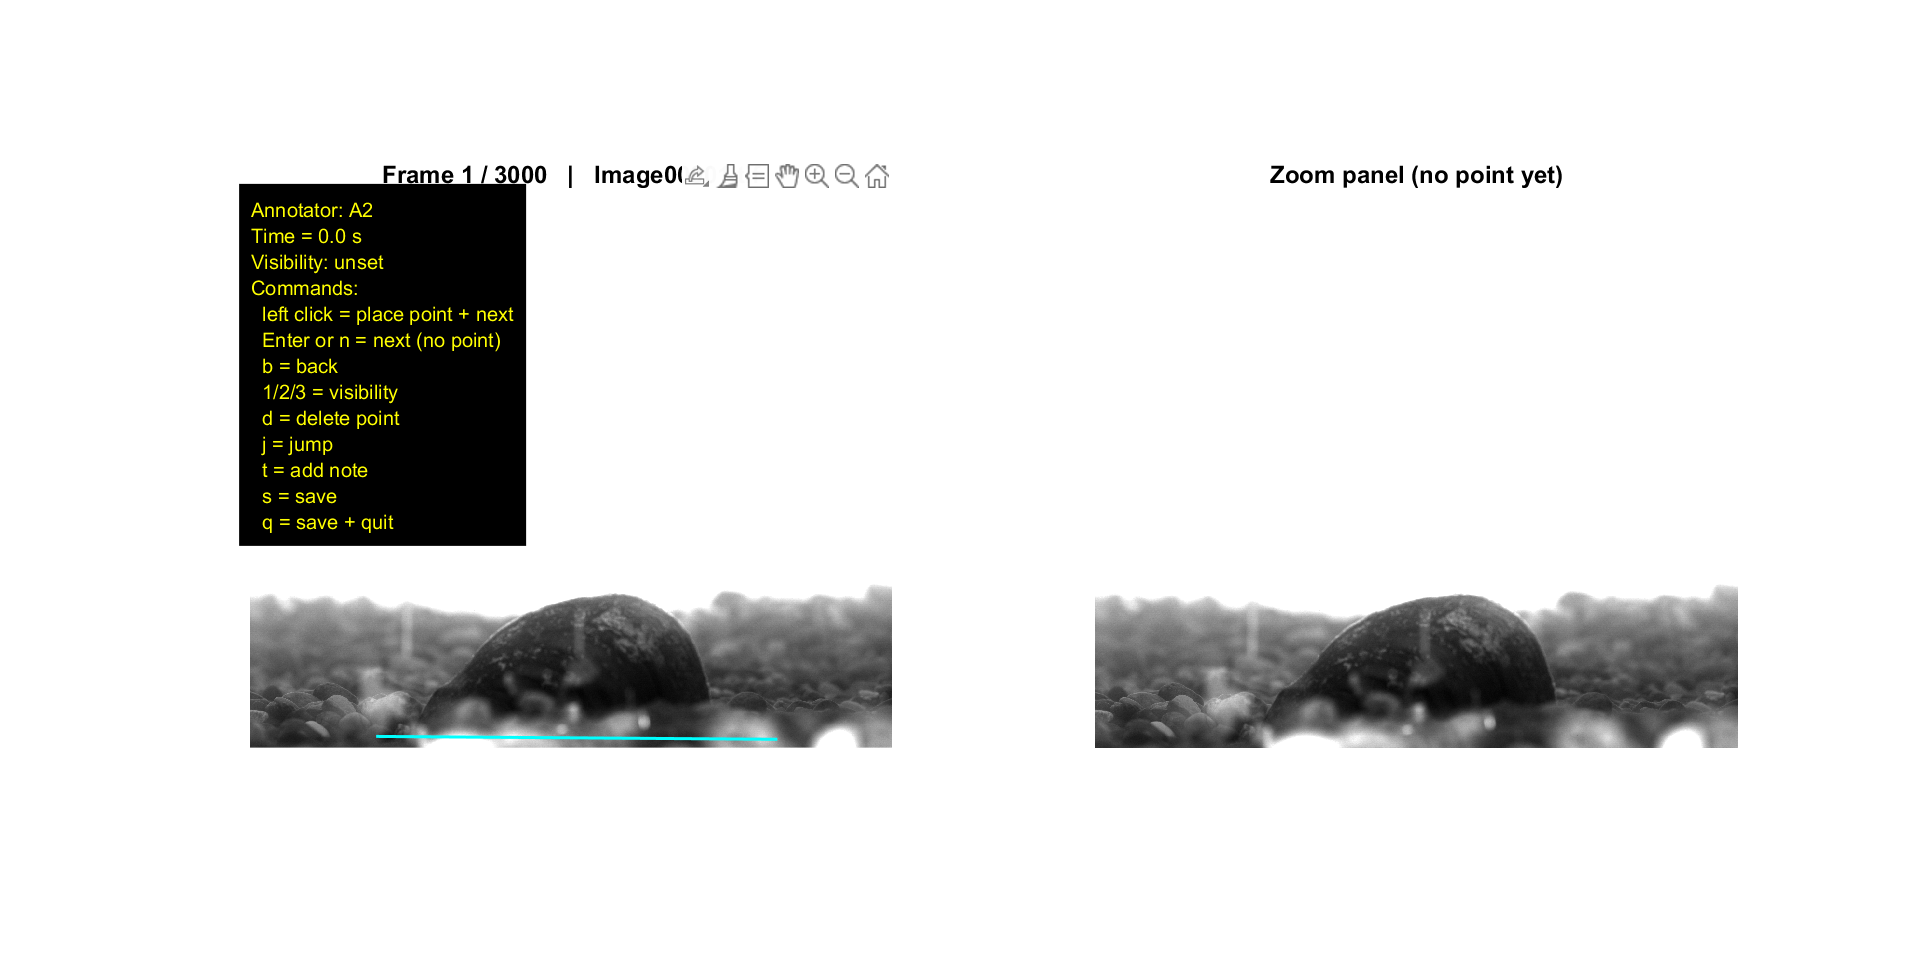

Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.
Autosaved.

Reached last frame. Saved and exiting.



%% =====================================================================
%                         INITIALIZE OUTPUTS
% ======================================================================

ann.frame_idx            = (1:nFrames)';
ann.filename             = strings(nFrames,1);
ann.time_s               = zeros(nFrames,1);
ann.x_top_px             = nan(nFrames,1);
ann.y_top_px             = nan(nFrames,1);
ann.visibility_class     = nan(nFrames,1);   % 1 clear, 2 moderate, 3 high ambiguity
ann.visibility_label     = strings(nFrames,1);
ann.note                 = strings(nFrames,1);

% Optional bed-referenced quantities
ann.bed_y_at_x_px        = nan(nFrames,1);
ann.height_above_bed_px  = nan(nFrames,1);
ann.height_above_bed_mm  = nan(nFrames,1);
ann.burrow_depth_px      = nan(nFrames,1);
ann.burrow_depth_mm      = nan(nFrames,1);

for k = 1:nFrames
    ann.filename(k) = string(files(k).name);
    ann.time_s(k)   = (k-1) * params.dt;
end

outBase = sprintf('manual_annotations_%s', params.annotator_id);
csvFile = fullfile(params.output_dir, [outBase '.csv']);
matFile = fullfile(params.output_dir, [outBase '.mat']);

%% =====================================================================
%                            MAIN LOOP
% ======================================================================

k = 1;
nSinceSave = 0;

hFig = figure('Name', sprintf('Manual Shell-Top Annotator [%s]', params.annotator_id), ...
    'Color', 'w', 'NumberTitle', 'off', 'Units', 'normalized', ...
    'Position', [0.05 0.05 0.88 0.85]);

% Keep cursor as crosshair on every frame
set(hFig, 'Pointer', 'crosshair');

while ishandle(hFig)
    clf(hFig);

    I = imread(fullfile(params.folder, files(k).name));
    Ishow = I;

    % Main image panel
    ax1 = subplot(1, 2, 1, 'Parent', hFig);
    imshow(Ishow, [], 'Parent', ax1); hold(ax1, 'on');
    title(ax1, sprintf('Frame %d / %d   |   %s', k, nFrames, files(k).name), ...
        'FontSize', params.font_size, 'Interpreter', 'none');

    if bed.enabled
        plot(ax1, [bed.x1 bed.x2], [bed.y1 bed.y2], 'c-', 'LineWidth', 1.5);
    end

    if ~isnan(ann.x_top_px(k))
        plot(ax1, ann.x_top_px(k), ann.y_top_px(k), 'ro', ...
            'MarkerSize', params.marker_size, 'LineWidth', params.line_width);
    end

    infoStr = sprintf(['Annotator: %s\n' ...
                       'Time = %.1f s\n' ...
                       'Visibility: %s\n' ...
                       'Commands:\n' ...
                       '  left click = place point + next\n' ...
                       '  Enter or n = next (no point)\n' ...
                       '  b = back\n' ...
                       '  1/2/3 = visibility\n' ...
                       '  d = delete point\n' ...
                       '  j = jump\n' ...
                       '  t = add note\n' ...
                       '  s = save\n' ...
                       '  q = save + quit'], ...
                       params.annotator_id, ann.time_s(k), current_visibility_label(ann.visibility_class(k)));
    text(ax1, 10, 30, infoStr, 'Color', 'y', 'FontSize', 10, ...
        'VerticalAlignment', 'top', 'BackgroundColor', 'k', 'Margin', 6);

    % Zoom panel
    if params.show_zoom_panel
        ax2 = subplot(1, 2, 2, 'Parent', hFig);
        if ~isnan(ann.x_top_px(k))
            [cropIm, xlimZoom, ylimZoom] = get_zoom_patch(Ishow, ann.x_top_px(k), ann.y_top_px(k), ...
                params.zoom_half_width, params.zoom_half_height);
            imshow(cropIm, [], 'Parent', ax2); hold(ax2, 'on');
            title(ax2, 'Zoom around current annotation', 'FontSize', params.font_size);

            xLocal = ann.x_top_px(k) - xlimZoom(1) + 1;
            yLocal = ann.y_top_px(k) - ylimZoom(1) + 1;
            plot(ax2, xLocal, yLocal, 'ro', 'MarkerSize', params.marker_size, 'LineWidth', params.line_width);

            if bed.enabled
                xx = [bed.x1 bed.x2];
                yy = [bed.y1 bed.y2];
                xxLocal = xx - xlimZoom(1) + 1;
                yyLocal = yy - ylimZoom(1) + 1;
                plot(ax2, xxLocal, yyLocal, 'c-', 'LineWidth', 1.2);
            end
        else
            imshow(Ishow, [], 'Parent', ax2);
            title(ax2, 'Zoom panel (no point yet)', 'FontSize', params.font_size);
        end
    end

    drawnow;

    % Wait for user action
    figure(hFig);
    [x, y, button] = ginput(1);

    if isempty(button)
        button = 13; % Enter
    end

    switch button
        case 1   % left click = place point + auto-advance
            ann.x_top_px(k) = x;
            ann.y_top_px(k) = y;

            if bed.enabled
                bedY = bed_y_at_x(bed, x);
                ann.bed_y_at_x_px(k)       = bedY;
                ann.height_above_bed_px(k) = bedY - y;
                ann.height_above_bed_mm(k) = ann.height_above_bed_px(k) * params.mm_per_px;

                if ~isempty(params.mussel_length_px)
                    ann.burrow_depth_px(k) = params.mussel_length_px - ann.height_above_bed_px(k);
                    ann.burrow_depth_mm(k) = ann.burrow_depth_px(k) * params.mm_per_px;
                end
            end

            nSinceSave = nSinceSave + 1;

            if k < nFrames
                k = k + 1;
            else
                save_outputs(csvFile, matFile, ann, params, bed);
                fprintf('Reached last frame. Saved and exiting.\n');
                break;
            end

        case {13, 110}  % Enter or 'n' = next frame without placing a point
            k = min(k+1, nFrames);
            nSinceSave = nSinceSave + 1;

        case 98  % 'b'
            k = max(k-1, 1);

        case 49  % '1'
            ann.visibility_class(k) = 1;
            ann.visibility_label(k) = "clear";

        case 50  % '2'
            ann.visibility_class(k) = 2;
            ann.visibility_label(k) = "moderate";

        case 51  % '3'
            ann.visibility_class(k) = 3;
            ann.visibility_label(k) = "high_ambiguity";

        case 100 % 'd'
            ann.x_top_px(k)            = nan;
            ann.y_top_px(k)            = nan;
            ann.bed_y_at_x_px(k)       = nan;
            ann.height_above_bed_px(k) = nan;
            ann.height_above_bed_mm(k) = nan;
            ann.burrow_depth_px(k)     = nan;
            ann.burrow_depth_mm(k)     = nan;

        case 106 % 'j'
            answer = inputdlg(sprintf('Jump to frame (1-%d):', nFrames), ...
                              'Jump to frame', [1 40], {num2str(k)});
            if ~isempty(answer)
                kk = str2double(answer{1});
                if ~isnan(kk) && kk >= 1 && kk <= nFrames
                    k = round(kk);
                end
            end

        case 116 % 't'
            answer = inputdlg('Note for current frame:', ...
                              'Frame note', [3 50], {char(ann.note(k))});
            if ~isempty(answer)
                ann.note(k) = string(answer{1});
            end

        case 115 % 's'
            save_outputs(csvFile, matFile, ann, params, bed);
            fprintf('Saved progress to:\n  %s\n  %s\n', csvFile, matFile);
            nSinceSave = 0;

        case 113 % 'q'
            save_outputs(csvFile, matFile, ann, params, bed);
            fprintf('Saved and exiting.\n');
            break;

        otherwise
            % ignore
    end

    if nSinceSave >= params.autosave_every
        save_outputs(csvFile, matFile, ann, params, bed);
        fprintf('Autosaved.\n');
        nSinceSave = 0;
    end
end


if ishandle(hFig)
    close(hFig);
end

%% =====================================================================
%                              FUNCTIONS
% ======================================================================

function save_outputs(csvFile, matFile, ann, params, bed)
    T = table(ann.frame_idx, ann.filename, ann.time_s, ...
              ann.x_top_px, ann.y_top_px, ...
              ann.visibility_class, ann.visibility_label, ann.note, ...
              ann.bed_y_at_x_px, ...
              ann.height_above_bed_px, ann.height_above_bed_mm, ...
              ann.burrow_depth_px, ann.burrow_depth_mm, ...
              'VariableNames', {'frame_idx','filename','time_s', ...
                                'x_top_px','y_top_px', ...
                                'visibility_class','visibility_label','note', ...
                                'bed_y_at_x_px', ...
                                'height_above_bed_px','height_above_bed_mm', ...
                                'burrow_depth_px','burrow_depth_mm'});
    writetable(T, csvFile);
    save(matFile, 'ann', 'params', 'bed');
end

function label = current_visibility_label(v)
    if isnan(v)
        label = 'unset';
    elseif v == 1
        label = 'clear';
    elseif v == 2
        label = 'moderate';
    elseif v == 3
        label = 'high ambiguity';
    else
        label = 'unset';
    end
end

function yb = bed_y_at_x(bed, x)
    if ~bed.enabled
        yb = nan;
        return;
    end
    if abs(bed.x2 - bed.x1) < eps
        yb = mean([bed.y1 bed.y2]);
    else
        m = (bed.y2 - bed.y1) / (bed.x2 - bed.x1);
        yb = bed.y1 + m * (x - bed.x1);
    end
end

function [cropIm, xlimZoom, ylimZoom] = get_zoom_patch(I, x, y, hw, hh)
    [H, W, ~] = size(I);
    x1 = max(1, floor(x - hw));
    x2 = min(W, ceil(x + hw));
    y1 = max(1, floor(y - hh));
    y2 = min(H, ceil(y + hh));
    cropIm = I(y1:y2, x1:x2, :);
    xlimZoom = [x1 x2];
    ylimZoom = [y1 y2];
end

function bed = draw_bedline(I, params)
    h = figure('Name','Draw fixed bed line','Color','w');
    imshow(I, []); hold on;
    title({'Draw the fixed bed line used for all manual annotations', ...
           'Click two points along the bed, then press Enter'}, ...
           'FontSize', params.font_size);
    [x, y] = getline(gca, 'closed');
    if numel(x) < 2
        error('Bed line drawing requires at least two points.');
    end
    bed.enabled = true;
    bed.x1 = x(1);
    bed.y1 = y(1);
    bed.x2 = x(end);
    bed.y2 = y(end);
    close(h);
end

function bed = parse_bedline_struct(S)
    % Robust loading from different possible saved bed-line formats

    bed = struct('enabled', true, 'x1', [], 'y1', [], 'x2', [], 'y2', []);

    % Case 1: direct fields
    if all(isfield(S, {'x1','y1','x2','y2'}))
        bed.x1 = S.x1;
        bed.y1 = S.y1;
        bed.x2 = S.x2;
        bed.y2 = S.y2;
        return;
    end

    % Case 2: nested struct with x1,y1,x2,y2
    nestedNames = {'bed','bedline','bed_line','bedLine'};
    for i = 1:numel(nestedNames)
        name = nestedNames{i};
        if isfield(S, name)
            b = S.(name);

            if isstruct(b) && all(isfield(b, {'x1','y1','x2','y2'}))
                bed.x1 = b.x1;
                bed.y1 = b.y1;
                bed.x2 = b.x2;
                bed.y2 = b.y2;
                return;
            end

            if isnumeric(b) && ismatrix(b) && size(b,2) == 2 && size(b,1) >= 2
                bed.x1 = b(1,1);
                bed.y1 = b(1,2);
                bed.x2 = b(end,1);
                bed.y2 = b(end,2);
                return;
            end
        end
    end

    % Case 3: bedModel struct with p1 and p2
    if isfield(S, 'bedModel')
        bm = S.bedModel;

        if isstruct(bm) && all(isfield(bm, {'p1','p2'}))
            p1 = bm.p1;
            p2 = bm.p2;

            if isnumeric(p1) && isnumeric(p2) && numel(p1) >= 2 && numel(p2) >= 2
                p1 = p1(:)';
                p2 = p2(:)';
                bed.x1 = p1(1);
                bed.y1 = p1(2);
                bed.x2 = p2(1);
                bed.y2 = p2(2);
                return;
            end
        end
    end

    % Case 4: linePts as Nx2
    if isfield(S, 'linePts')
        P = S.linePts;
        if isnumeric(P) && ismatrix(P) && size(P,2) == 2 && size(P,1) >= 2
            bed.x1 = P(1,1);
            bed.y1 = P(1,2);
            bed.x2 = P(end,1);
            bed.y2 = P(end,2);
            return;
        end
    end

    % Case 5: separate x/y vectors
    xyPairs = {
        'x_bed','y_bed';
        'xBed','yBed';
        'xb','yb';
        'x','y'
    };

    for i = 1:size(xyPairs,1)
        xname = xyPairs{i,1};
        yname = xyPairs{i,2};
        if isfield(S, xname) && isfield(S, yname)
            xv = S.(xname);
            yv = S.(yname);

            if isnumeric(xv) && isnumeric(yv) && numel(xv) >= 2 && numel(yv) >= 2
                xv = xv(:);
                yv = yv(:);
                bed.x1 = xv(1);
                bed.y1 = yv(1);
                bed.x2 = xv(end);
                bed.y2 = yv(end);
                return;
            end
        end
    end

    % Case 6: search any Nx2 numeric array
    fields = fieldnames(S);
    for i = 1:numel(fields)
        v = S.(fields{i});
        if isnumeric(v) && ismatrix(v) && size(v,2) == 2 && size(v,1) >= 2
            bed.x1 = v(1,1);
            bed.y1 = v(1,2);
            bed.x2 = v(end,1);
            bed.y2 = v(end,2);
            return;
        end
    end

    error('Could not parse bed line from file.');
end

function [sorted, idx] = sort_nat(c)
    % Natural-order sort for filenames like Image1, Image2, Image10
    expr = '\d+';
    keys = regexprep(c, expr, '${sprintf(''%08d'', str2double($0))}');
    [~, idx] = sort(lower(keys));
    sorted = c(idx);
end